# 실습#1: 이체운동(Two-Body Dynamics)

**[2024-가을] 우주비행역학(ASE3080), 인하대학교 항공우주공학과**

**목성훈(shmok@inha.ac.kr)**

% 초기화
clear all; 
close all;
clc;
format long

### 1. 타원 운동(elliptic motion)

#### 1.1. 위성 궤적 생성

지구 중력 상수와 지구 반지름을 정의합니다.

mu = 398600;        % [km3/s2] Earth gravitational constant
R = 6371;           % [km] Earth radius

먼저 임의 궤도로 9000 km 장반경, 이심율 0.2 타원 궤도를 정의합니다.

a = 9000 % [km] semi-major axis (SMA)

a =         9000


e = 0.2 % [] eccentricity

e =    0.200000000000000


타원 모양이 어떤지 그려볼까요? 먼저 통반경(semi-latus rectum) $p$와 단반경(semi-minor axis) $b$를 구해봅니다.


$$\begin{array}{l}
p=a\left(1-e^2 \right)\\
b=a\sqrt{\left(1-e^2 \right)}
\end{array}$$


p = a * (1-e^2)% [km] semi-latus rectum

p =         8640


b = a * sqrt(1-e^2)% [km] semi-minor axis

b =      8.818163074019441e+03


근점 편각(true anomaly) $f$를 0부터 360도까지 키워가며 반경(radius) $r$을 구합니다. 


$$r=\frac{p}{1+\textrm{ecosf}}$$


f = linspace(0, 2*pi, 30) % [rad] true anomaly

f =                    0   0.216661562316537   0.433323124633075   0.649984686949612   0.866646249266150   1.083307811582687   1.299969373899225   1.516630936215762   1.733292498532300   1.949954060848837   2.166615623165375   2.383277185481912   2.599938747798450   2.816600310114987   3.033261872431524   3.249923434748061   3.466584997064599   3.683246559381137   3.899908121697674   4.116569684014212   4.333231246330749   4.549892808647287   4.766554370963823   4.983215933280361   5.199877495596899   5.416539057913437   5.633200620229974   5.849862182546511   6.066523744863049   6.283185307179586


r = p ./(1+e*cos(f))% [km] radius

r = 1.0e+04 *

   0.720000000000000   0.722816508046952   0.731264468603368   0.745329647234376   0.764955641805702   0.789992197336154   0.820118986052995   0.854745007633577   0.892890728967152   0.933073198497819   0.973233173736501   1.010761685402112   1.042686719644387   1.066048929790377   1.078419564576719   1.078419564576719   1.066048929790377   1.042686719644387   1.010761685402112   0.973233173736501   0.933073198497819   0.892890728967152   0.854745007633577   0.820118986052995   0.789992197336154   0.764955641805702   0.745329647234376   0.731264468603368   0.722816508046952   0.720000000000000


위성 위치 $\mathit{\mathbf{r}}=\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\textrm{rcosf}\\
\textrm{rsinf}
\end{array}\right\rbrack$을 구할 수 있습니다. 위성 궤적과 지구를 함께 그려봅니다.

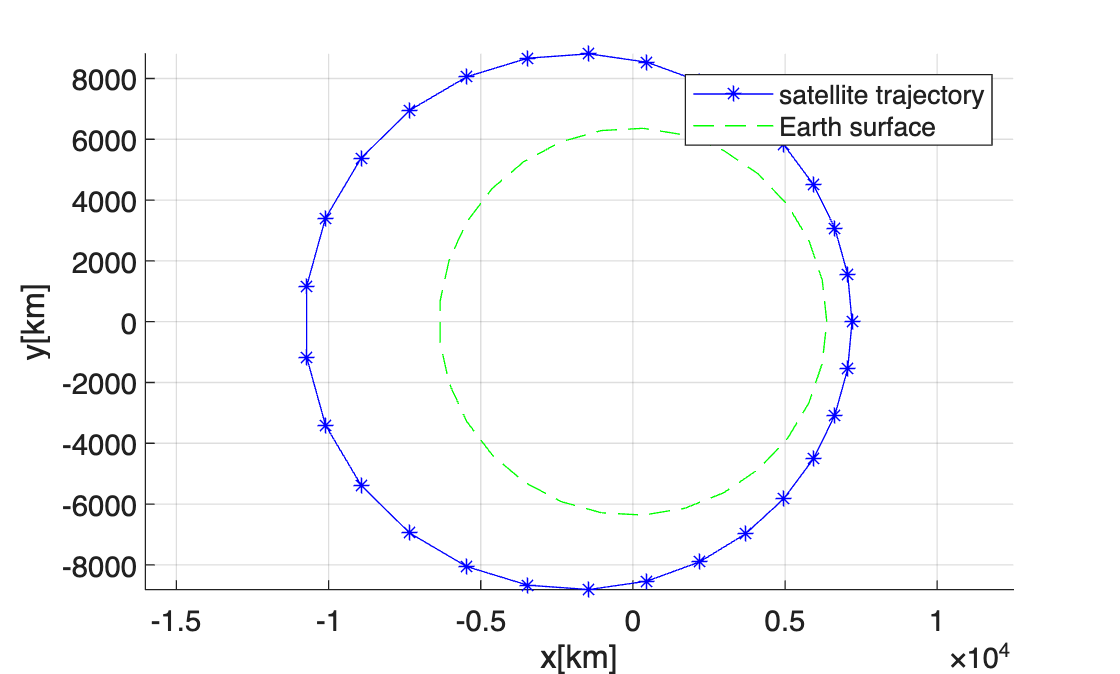

x = r .* cos(f);        % [km] 위성 위치 x 성분
y = r .* sin(f);        % [km] 위성 위치 y 성분
x_E = R * cos(f);       % [km] 지표면 x 성분
y_E = R * sin(f);       % [km] 지표면 y 성분
figure; grid on; hold on;
plot(x,y,'b-*');        % 위성 궤도
plot(x_E, y_E, 'g--');  % 지표면
legend('satellite trajectory', 'Earth surface');
xlabel('x[km]'); ylabel('y[km]');
axis equal

근지점 고도와 원지점 고도를 구해 봅시다.

rp = a*(1-e)% [km] 근지점 반경

rp =         7200


ra = a*(1+e)% [km] 원지점 반경

ra =        10800


hp = rp - R

hp =    829


ha = ra - R

ha =         4429


#### 1.2. 장반경, 이심율에 따른 궤도 변화

장반경이 늘어날 때 위성 궤도는 어떻게 변할까? 이심율은 0.2 로 고정한다.

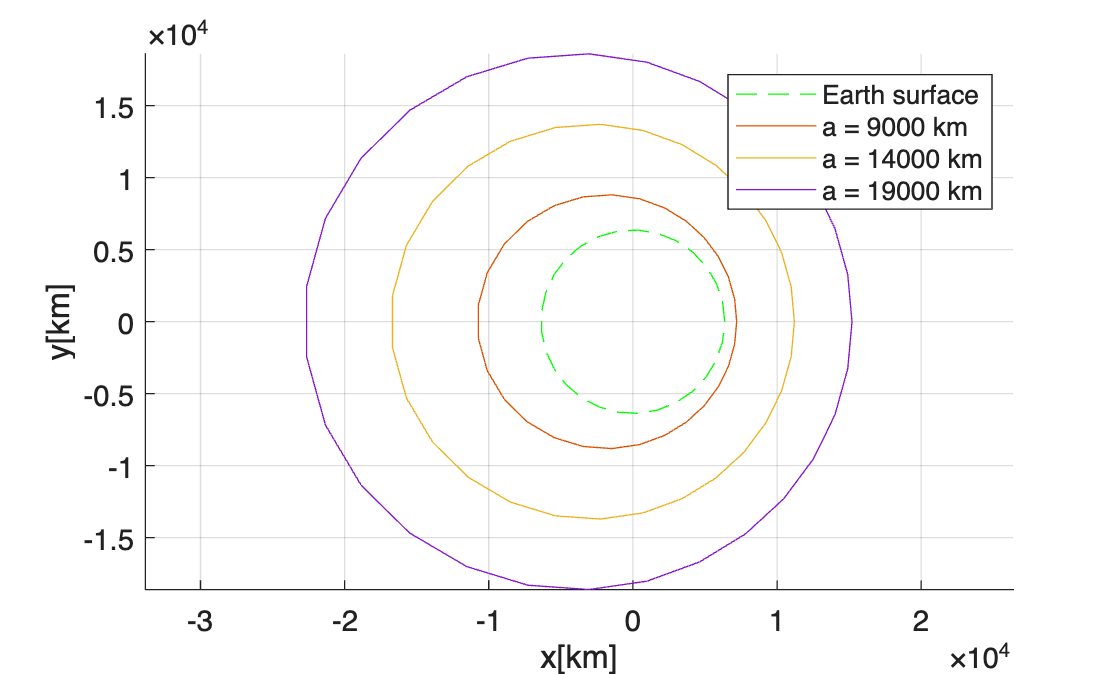

figure; hold on; grid on;
plot(x_E, y_E, 'g--', 'DisplayName', 'Earth surface');  % 지표면
for k = 1 : 1 : 3
    an = a + 5000 * (k-1);
    pn = an * (1-e^2);
    rn = pn ./ (1+e*cos(f));
    xn = rn .* cos(f);
    yn = rn .* sin(f);
    plot(xn, yn, '-', 'DisplayName', ['a = ', num2str(an), ' km']);
end
legend;
xlabel('x[km]'); ylabel('y[km]');
axis equal

이심율에 따른 궤도 변화는? 장반경은 20000 km 로 고정해 보자.

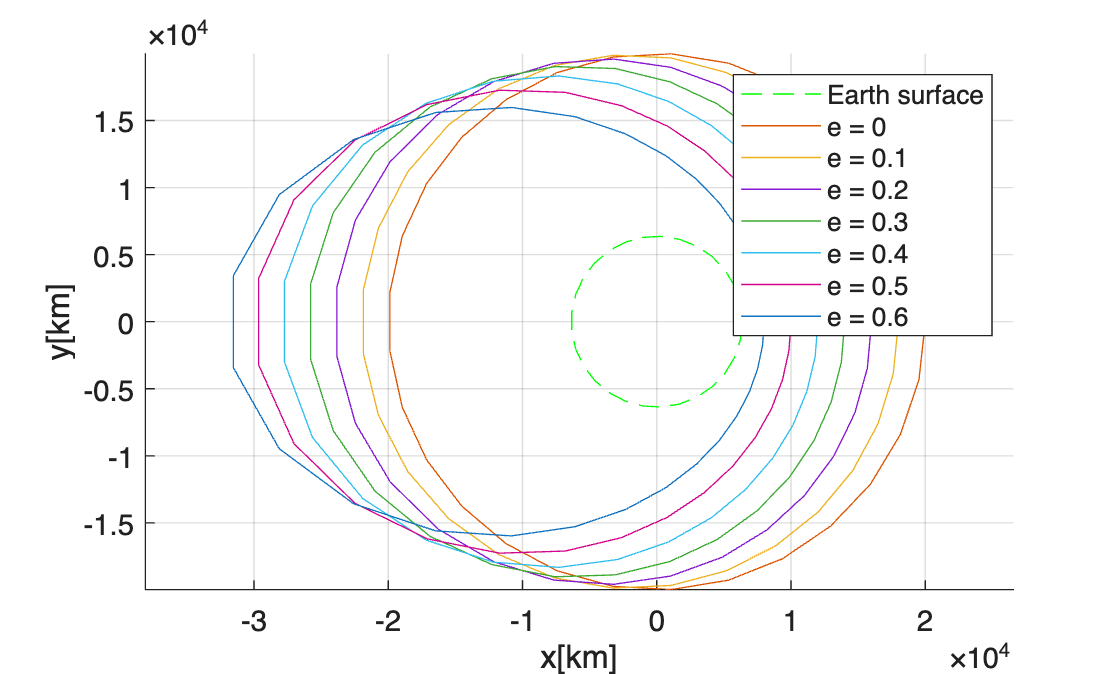

figure; hold on; grid on;
plot(x_E, y_E, 'g--', 'DisplayName', 'Earth surface');  % 지표면
an = 20000;
en = 0 : 0.1 : 0.6;
for k = 1 : 1 : length(en)
    e = en(k);
    pn = an * (1-e^2);
    rn = pn ./ (1+e*cos(f));
    xn = rn .* cos(f);
    yn = rn .* sin(f);
    plot(xn, yn, '-', 'DisplayName', ['e = ', num2str(e)]);
end
legend;
xlabel('x[km]'); ylabel('y[km]');
axis equal

### 2. 이체 운동(two body motion)

#### 2.1. 수치 적분을 통한 궤도 전파

수치 적분을 통해 위성 초기 상태(위치, 속도) ${\mathit{\mathbf{x}}}_{\;0} =\left\lbrack \begin{array}{c}
{\mathit{\mathbf{r}}}_{0\;} \\
{\mathit{\mathbf{v}}}_{\;0} 
\end{array}\right\rbrack$로부터 궤도를 구해 보자. 이차원 운동을 가정한다. 위성이 초기에 근지점에 위치한다고 가정할 때 초기 위치 벡터 ${\mathit{\mathbf{r}}}_{\;0} =\left\lbrack \begin{array}{c}
x_{\;0} \\
y_{\;0} 
\end{array}\right\rbrack$, 속도 벡터 ${\mathit{\mathbf{v}}}_{\;0} =\left\lbrack \begin{array}{c}
{\dot{x} }_{\;0} \\
{\dot{y} }_{\;0} 
\end{array}\right\rbrack$는 다음과 같이 구할 수 있다. 장반경은 9000 km, 이심율 0.2 로 가정한다.

mu = 398600;        % [km3/s2] Earth gravitational constant
R = 6371;           % [km] Earth radius
a = 9000;
e = 0.2;
r = a * (1-e);
p = a * (1-e^2);
h = sqrt(mu * p)

h =      5.868478508097307e+04


v = h / r

v =    8.150664594579593


r0 = [r ; 0]% [km] position vector 

r0 =         7200
           0


v0 = [0 ; v]% [km/s] velocity vector

v0 =                    0
   8.150664594579593


x0 = [r0 ; v0]% satellite orbital state

x0 = 1.0e+03 *

   7.200000000000000
                   0
                   0
   0.008150664594580


수치 적분을 하려면 적분기를 선택하고 적분 길이 $T$를 결정해야 한다. 적분기는 Runge-Kutta 45차를, 적분 길이는 공전 주기로부터 구한다.

n = sqrt(mu/a^3)% [rad/s] mean orbital speed

n =      7.394433081958788e-04


T = 2*pi/n% [sec] orbital period

T =      8.497183269545754e+03


tspan = [ 0 T ]

tspan = 1.0e+03 *

                   0   8.497183269545754


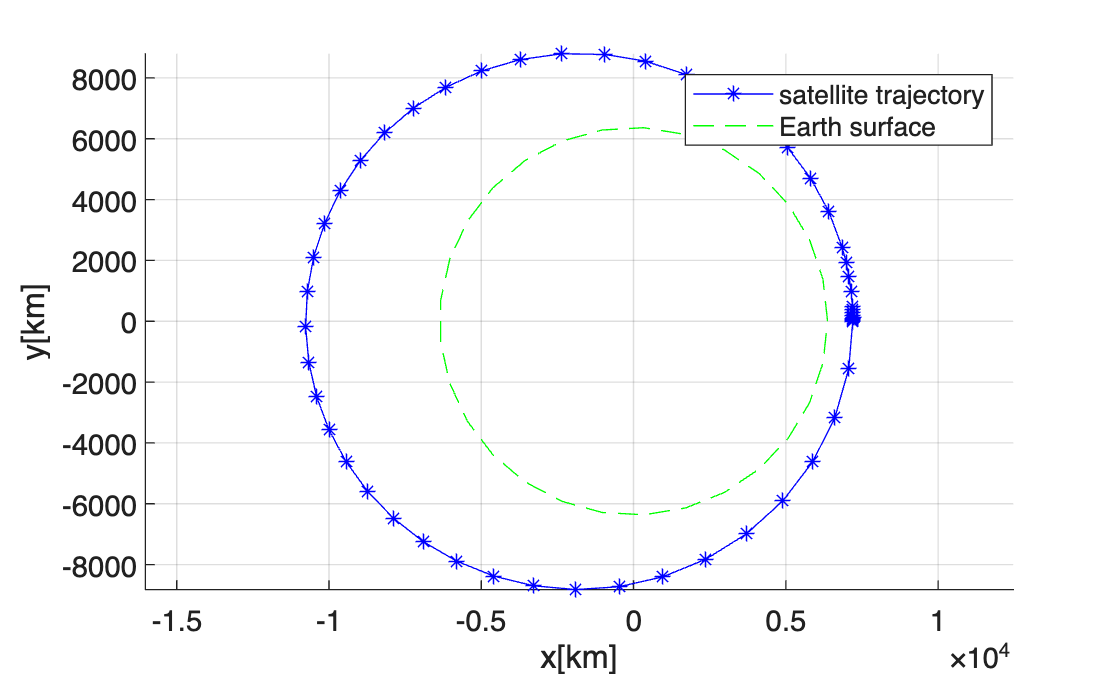

[t,x] = ode45(@(t,x) odeTwoBody(t,x,mu), tspan, x0);
figure; hold on; grid on;
plot(x(:,1),x(:,2),'b-*');      % 위성 궤도
plot(x_E, y_E, 'g--');          % 지표면
legend('satellite trajectory', 'Earth surface');
xlabel('x[km]'); ylabel('y[km]');
axis equal

수치 적분으로 구한 궤적과 타원 파라미터를 이용해 구한 궤적을 비교한다.

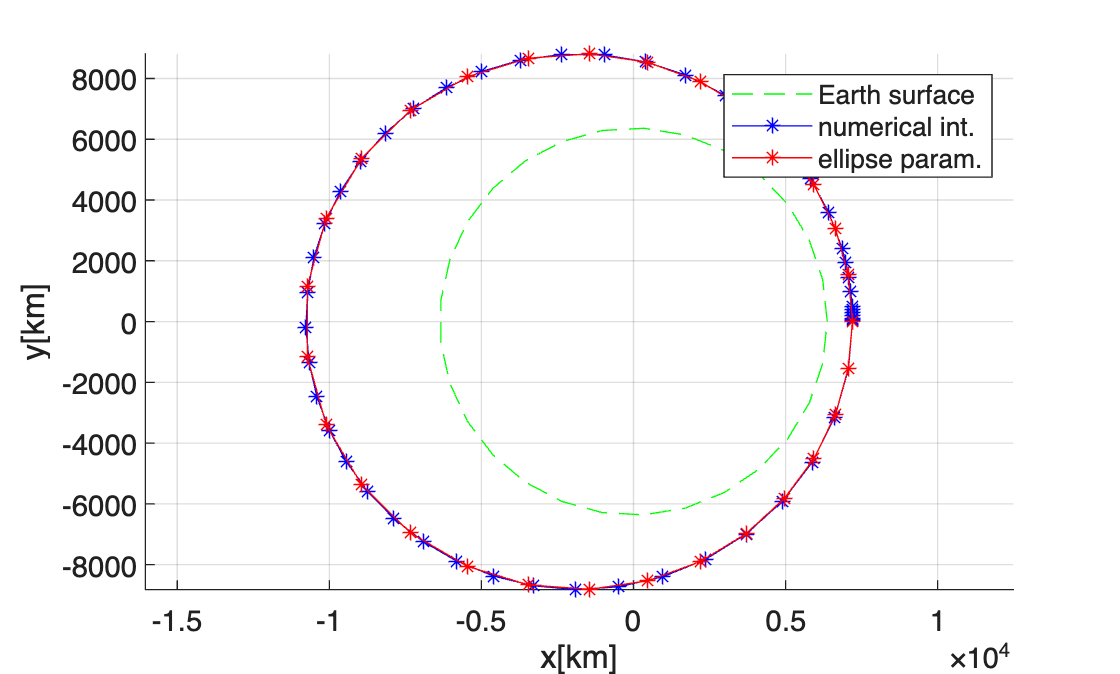

figure; hold on; grid on;
plot(x_E, y_E, 'g--', 'DisplayName', 'Earth surface');              % 지표면
plot(x(:,1),x(:,2),'b-*', 'DisplayName', 'numerical int.');         % 1) 수치 적분
r = p ./ (1+e*cos(f));
plot(r.*cos(f), r.*sin(f),'r-*', 'DisplayName', 'ellipse param.');  % 2) 타원 파라미터
legend;
xlabel('x[km]'); ylabel('y[km]');
axis equal

#### 2.2. 궤도에너지(vis-viva 방정식)

Vis-viva 방정식으로부터 장반경을 구해보고, 실제 장반경과 비교해보자.


$$a=-\frac{\mu }{2\epsilon \;}$$



$$\epsilon =\frac{v^{\;2} }{\;2}-\frac{\mu }{r}$$


rmag = norm(r0)% [km] radius

rmag =         7200


vmag = norm(v0)% [km/s] velocity

vmag =    8.150664594579593


epsilon = vmag^2/2 -mu/rmag ; % mechanical energy (point-mass)
a_vis = -mu / 2 / epsilon ;% [km] SMA from vis-viva eq.
a

a =         9000


#### 2.3. 탈출 속도(exit velocity)

탈출 속도 $v_{\;\infty }$란 위성이 중심 천체 중력장으로 벗어나기 위해 필요한 속도를 말한다. 다른 말로는 위성을 $r\to \infty$로 보낼 수 있는 속도로 궤도 에너지가 0이 되기 위해 필요한 속도를 의미한다.


$$v_{\;\infty } =\sqrt{\;\frac{2\mu }{r}\;\;}$$


먼저 근지점에서의 탈출 속도를 계산한다.

a = 9000;
e = 0.2;
r = a * (1-e);
ve = sqrt(2*mu/r)

ve =   10.522462745109731


근지점 속도가 증가할수록 장반경, 이심율, 궤도에너지가 어떻게 바뀌는지 확인해보자.

p = a * (1-e^2);
h = sqrt(mu * p)

h =      5.868478508097307e+04


v = h / r

v =    8.150664594579593


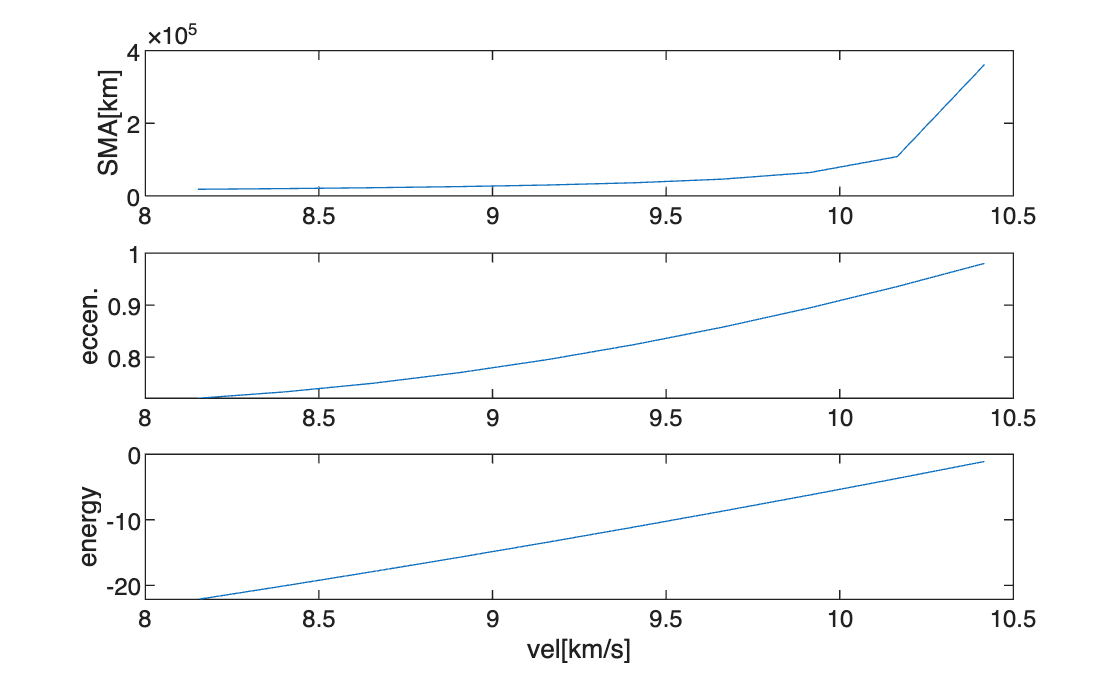

v = linspace(v,ve*0.99,10);
epsilon = v.^2 / 2 - mu / r;
a = - mu ./ epsilon;
h = r .* v;
e = sqrt( (mu*a - h.^2) ./ (mu.*a) );
figure;
subplot(311); grid on;
plot(v,a); ylabel('SMA[km]');
subplot(312); grid on;
plot(v,e); ylabel('eccen.');
subplot(313); grid on;
plot(v,epsilon); ylabel('energy'); xlabel('vel[km/s]');

### 3. 궤적 시각화

#### 3.1 3차원 애니메이션

MATLAB의 Aerospace Toolbox를 쓰면 조금 더 그럴듯한 애니메이션을 만들 수도 있습니다. [MATLAB Help](https://www.mathworks.com/help/aerotbx/index.html?searchHighlight=aerospace%20toolbox&s_tid=srchtitle_support_results_1_aerospace%20toolbox)

우선 아래와 같이 위성 시나리오를 생성합니다.

startTime = datetime(2025, 12, 19, 15, 0, 0);
simulationDuration = 0.5 % [day] 시뮬레이션 길이(0.5일, 12시간)

simulationDuration =    0.500000000000000


stopTime = startTime + days(simulationDuration);
sampleTime = 60;
sc = satelliteScenario(startTime, stopTime, sampleTime);

위성 궤도를 정의합니다.

a = 9000 * 1e3; % [km] semi-major axis
e = 0.2;        % [] eccentricity
inc = 97.8;     % [deg] inclination
Omega = 0;      % [deg] right ascension of ascending node (RAAN)
w = 0;          % [deg] argument of periapsis (AOP)
f = 0;          % [deg] true anomaly
sat = satellite(sc, a, e, inc, Omega, w, f, 'OrbitPropagator', 'two-body-keplerian', 'Name', 'INHA');

생성한 궤도를 3차원 좌표계에서 나타내 봅시다.

show(sat);

원한다면 지표면으로 투영한 위성 위치(위도, 경도)도 같이 그려볼 수 있습니다.

groundTrack(sat);

#### 3.2 2차원 지상궤적

또한 위경도 성분을 받아 2차원 평면에서 표현할 수 있습니다.

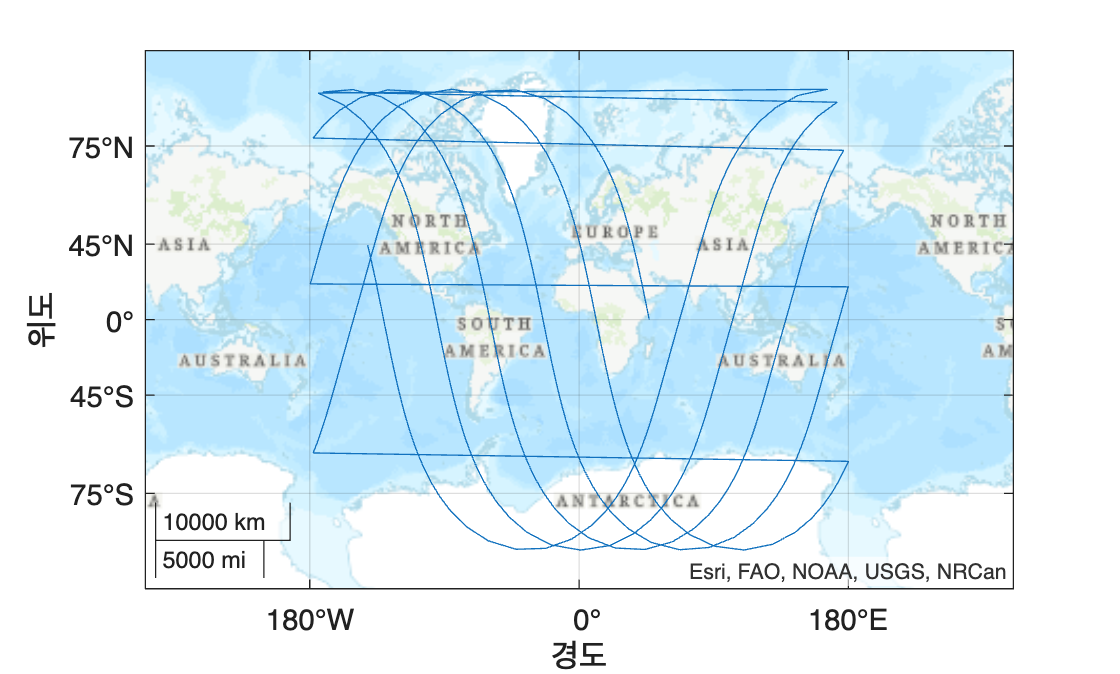

[LLA, vel, timeout] = states(sat, 'CoordinateFrame', 'geographic');
figure;
geoplot(LLA(1,:), LLA(2,:));
geobasemap topographic

#### 3.3 이벤트 예측(지상국 접속시간 분석)

지상국과 교신가능한 시간을 분석해 봅시다. 우선 지상국 객체를 생성합니다. 위성 교신 최소 고도는 10도로 설정한다.

lat = 37.383981;    % [deg] 위도(구글어스 검색 가능. 항공우주산학융합원)
lon = 126.657319;   % [deg] 경도
alt = 0;            % [m] 해발고도
angle = 10;         % [deg] 최소교신각도
gs = groundStation(sc,'Name','INHA-AE','Latitude',lat,'Longitude',lon,'Altitude',alt,'MinElevationAngle',angle);

지상국 접속시간을 분석해본다. access 함수를 사용할 수 있다.

ac = access(gs,sat);
intvls = accessIntervals(ac)

intvls = 3×8 table
     Source      Target    IntervalNumber         StartTime               EndTime          Duration    StartOrbit    EndOrbit
    _________    ______    ______________    ___________________    ___________________    ________    __________    ________

    "INHA-AE"    "INHA"          1           2025-12-19 20:18:00    2025-12-19 20:57:00      2340          3            3    
    "INHA-AE"    "INHA"          2           2025-12-19 22:38:00    2025-12-19 23:16:00      2280          4            4    
    "INHA-AE"    "INHA"          3           2025-12-20 01:00:00    2025-12-20 01:20:00      1200          5            5    


또한 지상국 접속상황에서 위성과 교신하기 위한 지상국의 방위각, 고도각을 aer 함수(azimuth, elevation, range)를 이용해 계산할 수 있다. 이는 지상국 운영(안테나 지향 등)에 활용할 수 있다.

TimeIn = [];
for ind = 1:1:length(intvls.Duration)
    TimeIn = [TimeIn ; intvls.StartTime(ind) + seconds([0:sampleTime:intvls.Duration(ind)]')];
end

az = zeros(length(TimeIn(:,1)),1);
el = zeros(length(TimeIn(:,1)),1);
range = zeros(length(TimeIn(:,1)),1);

for ind = 1:1:length(TimeIn(:,1))
    [az(ind), el(ind), range(ind)] = aer(gs,sat,TimeIn(ind));
end

aerTable = table(TimeIn,az, el, range, 'VariableNames',["Access Time (UTC)", "Azimuth (deg)","Elevation (deg)", "Range (m)"])

aerTable = 100×4 table
     Access Time (UTC)      Azimuth (deg)      Elevation (deg)        Range (m)    
    ___________________    ________________    ________________    ________________

    2025-12-19 20:18:00    23.5468860730018    10.0264279071036    5775101.54998943
    2025-12-19 20:19:00    25.7693505907776    12.8945479737373    5619927.16164734
    2025-12-19 20:20:00    28.1409277632312    15.7993700788408    5473678.96592158
    2025-12-19 20:21:00     30.683252323828    18.7313625319182    5337031.26200872
    2025-12-19 20:22:00    33.4205683651318    21.6775997813157    5210656.91848847
    2025-12-19 20:23:00    36.3797529678303    24.6211716434424    5095216.41199225
    2025-12-19 20:24:00    39.5900920107779    27.5406072917066    4991344.51453606
    2025-12-19 20:25:00    43.0826431037204    30.4093777150564    4899634.78640454
    2025-12-19 20:26:00    46.8889598117487    33.1955674543275    4820622.48728263
    2025-12-19 20:27:00    51.0388972405011     35.8

#### 3.4 기타

Aerospace toolbox는 이외에 센서의 가시성 분석(conicalSensor 함수) 등도 수행할 수 있게 지원한다. 또한 관련된 toolbox에는 Satellite Communication Toolbox가 존재한다.

### 참고

*3장 궤적 시각화*는 부산대학교 조동현교수님의 2023 제26차 인공위성 단기강좌 샘플 파일을 참고하였습니다. 